# Factor Graph-Based Pedestrian Localization with IMU and GPS Sensors

This example shows how to estimate the position of a pedestrian using logged sensor data from an inertial measurement unit (IMU) and Global Positioning System (GPS) receiver and a factor graph. 

A factor graph is a bipartite graph, or bigraph. A bipartite graph contains vertices that can be divided into two disjoint and independent sets. The first set of vertices are factors and contain fixed measurements, usually from a sensor, and a corresponding uncertainty matrix for each measurement. The second set of vertices are state nodes and update during factor graph optimization. The goal of optimization is to minimize every cost function defined for each connection of a factor and a state. 

This example helper includes a function that plots a basic factor graph consisting of five factors and three state nodes, shown as blue squares and red circles respectively:

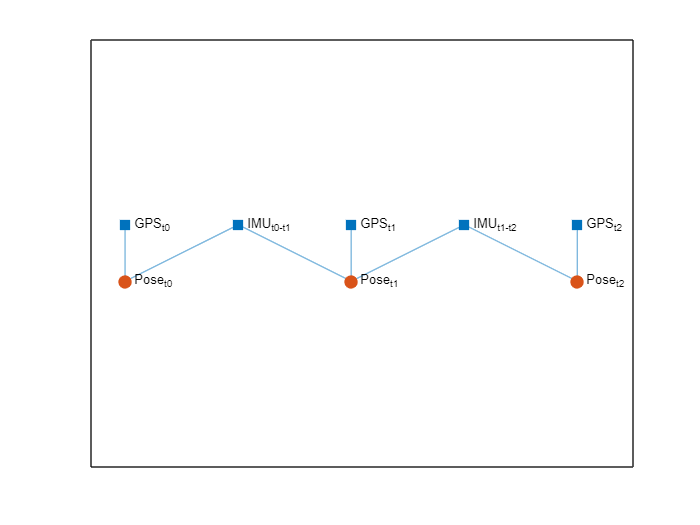

exampleHelperPlotBasicFactorGraph

The first factor, a GPS measurement at time `t0`, is connected to the first state node representing a pose at the same time `t0`. The second factor is all the IMU measurements between time `t0` and `t1`, and connects to both the first state node, a pose at `t0`, and the second state node, a pose at `t1`. During the optimization of the factor graph, the GPS and IMU factors constrain their connected pose states such that the new state value minimizes the value of the cost function corresponding to each factor.

## Load IMU and GPS Sensor Log File

Load a MAT file containing IMU and GPS sensor data, `pedestrianSensorDataIMUGPS`, and extract the sampling rate and noise values for the Iye'sMU, the sampling rate for the factor graph optimization, and the estimated position reported by the onboard filters of the sensors. This MAT file was created by logging data from a sensor held by a pedestrian walking on a pathway around the MathWorks campus. 

load("pedestrianSensorDataIMUGPS.mat","sensorData","imuFs","imuNoise", ...
     "numGPSSamplesPerOptim","posLLA","initOrient","initPos","numIMUSamplesPerGPS");
     % Initial Version

% load("IMUGNSS4FGO.mat","sensorData1","imuFs","imuNoise", ...
%      "numGPSSamplesPerOptim","posLLH","initOrient","initPOS","numIMUSamplesPerGPS");

% Available:  imuFs; numGPSSamplesPerOptim (f_GPS / f_FG: 100); 
%             numIMUSamplesPerGPS (f_IMU / f_GPS: ~100)； posLLA (GT)
%                                                                  ?@?1：numGPSSamplesPerOptim
% Unknown: imuNoise (struct); iniOrient(quaternion)  ?@?2  ; initPos; 
%          sensorData (type: struct);

%    ?@?3 sensorData{1, 2}.LastIMUReadingTimeStamp
%     
% 2022.03.19
% Done: imuFs, initPos, iniOrient, numGPSSamplesPerOptim, imuNoise, 
% Notyet: numIMUSamplesPerGPS, posLLA,
%         sensorData {NumIMUReadings, 
%                     LastIMUReadingTimeStamp, 
%                     HDOP, VDOP: %re-define data_all    ?@?4 }


## Create Factor Graph

This diagram shows the structure of a factor graph for processing the sensor data. For each iteration of the loop in the Estimate Pedestrian Position section, the time step updates and then advances to the next GPS reading. The process repeats until all of the sensor data has been processed. The diagram shows the relationship between the state nodes and factors for one pair of time steps or one iteration of the `for` loop. 

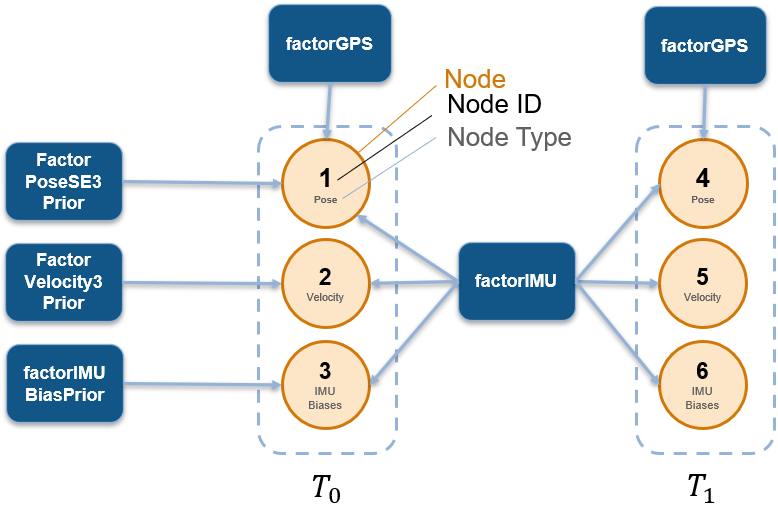

Create a vector to keep track of the current node IDs for each pair of time steps.

nodesPerTimeStep = [exampleHelperFactorGraphNodes.Pose; ...
                    exampleHelperFactorGraphNodes.Velocity; ...
                    exampleHelperFactorGraphNodes.IMUBias];
numNodesPerTimeStep = numel(nodesPerTimeStep);
currNodeIDs = nodesPerTimeStep + [0 numNodesPerTimeStep];
currNodeIDs = currNodeIDs(:).';

Create time index variables to easily access the current node IDs vector. The initial node IDs for pose, velocity, and IMU biases are defined in the helper function `exampleHelperFactorGraphNodes`. This makes the initialization process of this example clearer. 

t0IndexPose = exampleHelperFactorGraphNodes.Pose;
t1IndexPose = t0IndexPose + numNodesPerTimeStep;
t0IndexVel = exampleHelperFactorGraphNodes.Velocity;
t1IndexVel = t0IndexVel + numNodesPerTimeStep;
t0IndexBias = exampleHelperFactorGraphNodes.IMUBias;
t1IndexBias = t0IndexBias + numNodesPerTimeStep;

Create the factor graph as a [`factorGraph`](docid:nav_ref#mw_07fbc46b-a84c-4af7-af60-a0b84b53d4b4) object and the three prior factors as a [`factorPoseSE3Prior`](docid:nav_ref#mw_577d1cd9-07fa-4680-af07-d0efc04aa4f4), [`factorVelocity3Prior`](docid:nav_ref#mw_c7d2245d-05e5-4cc9-ac48-ac13cb66324c), and [`factorIMUBiasPrior`](docid:nav_ref#mw_70c09b74-b554-43dd-a40d-9ea2dbc546f3) object. Initialize the initial position, orientation, velocity, and IMU biases using the initial position and orientation from the onboard filter. The information matrix `Information` uses large values because they come from ground truth measurements. Add the prior factors to the factor graph using the [`addFactor`](docid:nav_ref#mw_9d916c92-185e-40a8-b2af-50ce7e15793b) function.

G = factorGraph;
prevPose =  [initPos compact(initOrient)]; % x y z | qw qx qy qz
prevVel = [0 0 0]; % m/s
prevBias = [0 0 0 0 0 0]; % Gyroscope and accelerometer biases.n        ??4: noise cov

fPosePrior = factorPoseSE3Prior(currNodeIDs(t0IndexPose),Measurement=prevPose, ...
    Information=diag([4e4 4e4 4e4 1e4 1e4 1e4]));
fVelPrior = factorVelocity3Prior(currNodeIDs(t0IndexVel),Measurement=prevVel, ...
    Information=100*eye(3));
fBiasPrior = factorIMUBiasPrior(currNodeIDs(t0IndexBias),Measurement=prevBias, ...
    Information=1e6*eye(6));

addFactor(G,fPosePrior);
addFactor(G,fVelPrior);
addFactor(G,fBiasPrior);

Set the state nodes connected to the prior factors to the initial values.

nodeState(G,currNodeIDs(t0IndexPose),prevPose);
nodeState(G,currNodeIDs(t0IndexVel),prevVel);
nodeState(G,currNodeIDs(t0IndexBias),prevBias);

Get the local geodetic origin for the navigation frame from the initial GPS reading.

lla0 = sensorData{1}.GPSReading;

Create solver options as a [`factorGraphSolverOptions`](docid:nav_ref#mw_cba44823-acbc-41ba-a949-010cc7b9cdf3) object, to use when optimizing the graph.

opts = factorGraphSolverOptions(MaxIterations=100);

Create a vector to store all the state node ID numbers that correspond to poses.

numGPSSamples = numel(sensorData);
poseIDs = zeros(1,numGPSSamples);

## Estimate Pedestrian Position

Process the logged sensor data and extract the pedestrian position estimate from the optimized factor graph. Create a plot to visualize the estimated position.

visHelper = Copy_of_exampleHelperVisualizeFactorGraphAndFilteredPosition;

Perform these operations for each GPS sample in the sensor data log:

- Store the current pose ID.

- Create an IMU factor.

- Create a GPS factor.

- Add the factors to the factor graph.

- Set initial node states using previous state estimates and a state prediction from the IMU measurements.

- Optimize the factor graph.

- Advance one time step by updating the previous state estimates to the current state and incrementing the current node IDs.

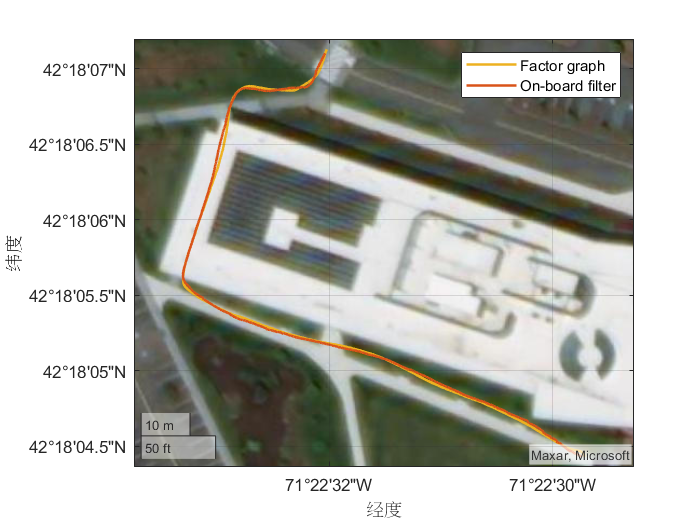

for ii = 1:numGPSSamples
    % 1. Store the current pose ID. 
    poseIDs(ii) = currNodeIDs(t0IndexPose);
    
    % 2. Create an IMU factor. 
        % imuFs: frequency of IMU (i.e.,400Hz)
    fIMU = factorIMU(currNodeIDs,imuFs, ...   
        imuNoise.GyroscopeBiasNoise, ...
        imuNoise.AccelerometerBiasNoise, ...
        imuNoise.GyroscopeNoise, ...
        imuNoise.AccelerometerNoise, ...
        sensorData{ii}.GyroReadings,sensorData{ii}.AccelReadings);

    % 3. Create a GPS factor. 
        % HDOP; VDOP
    fGPS = factorGPS(currNodeIDs(t0IndexPose),HDOP=sensorData{ii}.HDoP, ...
        VDOP=sensorData{ii}.VDoP, ...
        ReferenceLocation=lla0, ...
        Location=sensorData{ii}.GPSReading);

    % 4. Add the factors to the graph. 
    addFactor(G,fIMU);
    addFactor(G,fGPS);

    % 5. Set initial node states using previous state estimates and a state prediction from the IMU measurements.
    [predictedPose,predictedVel] = predict(fIMU,prevPose,prevVel,prevBias);
    nodeState(G,currNodeIDs(t1IndexPose),predictedPose);
    nodeState(G,currNodeIDs(t1IndexVel),predictedVel);
    nodeState(G,currNodeIDs(t1IndexBias),prevBias);
    
    % 6. Optimize the factor graph.
    if (mod(ii,numGPSSamplesPerOptim) == 0) || (ii == numGPSSamples)
        solnInfo = optimize(G,opts);

        % Visualize the current position estimate.
        updatePlot(visHelper,ii,G,poseIDs,posLLA,lla0,numIMUSamplesPerGPS);
        drawnow
    end

    % 7. Advance one time step by updating the previous state estimates to the current ones and incrementing the current node IDs.
    prevPose = nodeState(G,currNodeIDs(t1IndexPose));
    prevVel = nodeState(G,currNodeIDs(t1IndexVel));
    prevBias = nodeState(G,currNodeIDs(t1IndexBias));

    currNodeIDs = currNodeIDs + numNodesPerTimeStep;
end

The factor graph successfully estimates the position of the pedestrian compared to the position estimated by the onboard filter. To verify this, calculate the RMS error of the plotted 3-D position:

onBoardPos = lla2enu(posLLA,lla0,"ellipsoid");
onBoardPos = onBoardPos(cumsum(numIMUSamplesPerGPS-1),:); % Convert to sampling rate of factor graph.
estPos = zeros(numel(poseIDs),3);
for ii = 1:numel(poseIDs)
    currPose = nodeState(G, poseIDs(ii));
    estPos(ii,:) = currPose(1:3);
end
posDiff = estPos - onBoardPos;    
posDiff(isnan(posDiff(:,1)),:) = []; % Remove any missing position readings from the onboard filter.
posRMS = sqrt(mean(posDiff.^2));  
fprintf("3D Position RMS: X: %.2f, Y: %.2f, Z: %.2f (m)\n",posRMS(1),posRMS(2),posRMS(3));

3D Position RMS: X: 1.02, Y: 0.71, Z: 3.64 (m)


*Copyright 2021-2022 The MathWorks, Inc. *